# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'docx';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp


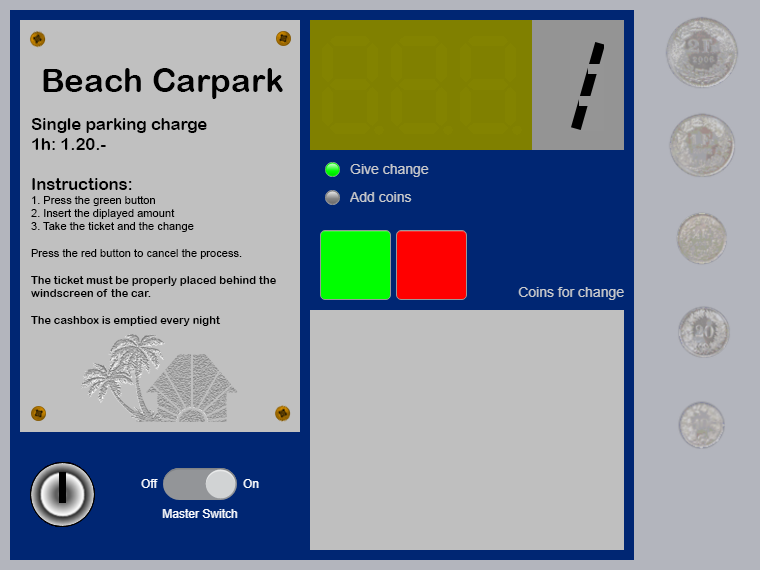

. Processing the test case #1...


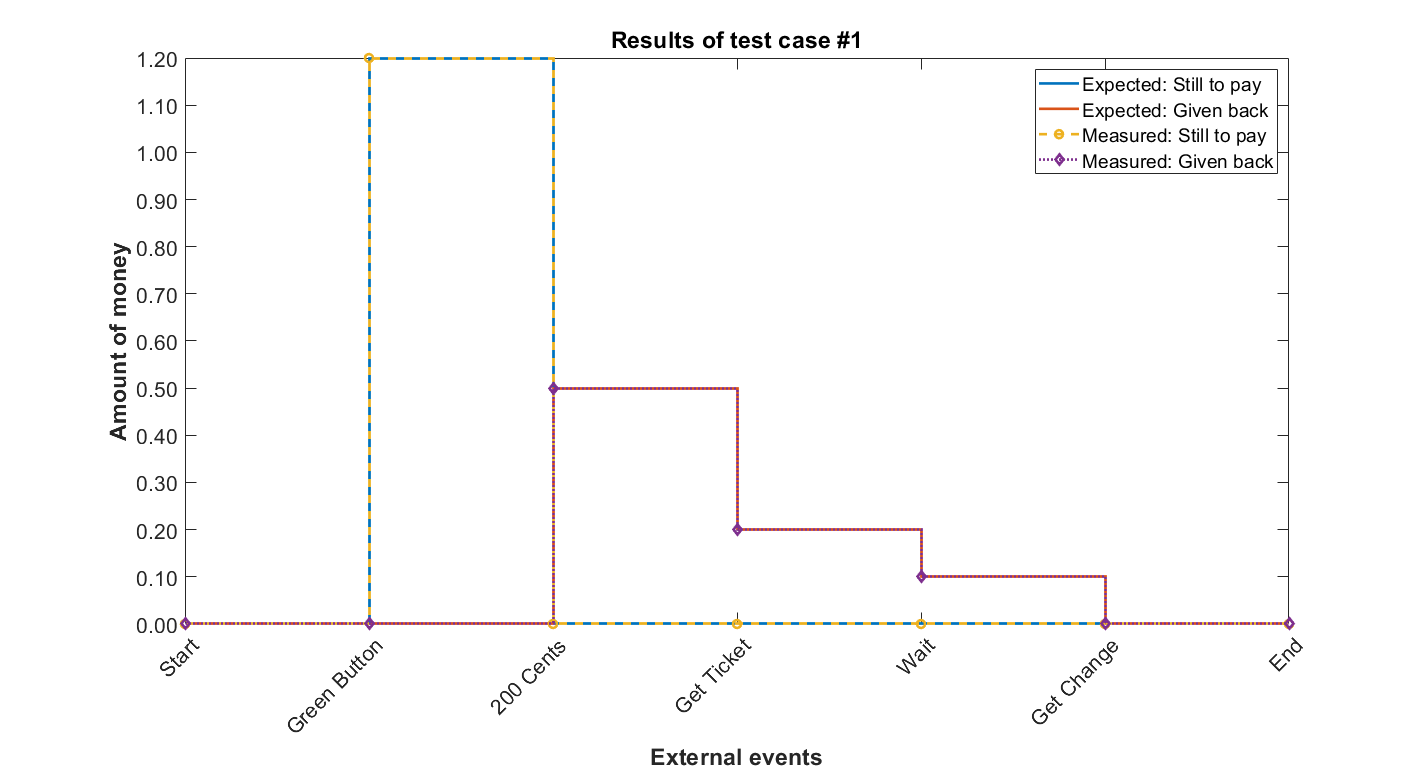


[Terse] Diagnostic logged (2021-02-11 15:53:09):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_434c872a-9436-4428-92ba-635d7b11eda0.fig
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_434c872a-9436-4428-92ba-635d7b11eda0.png
.

 Processing the test case #2...


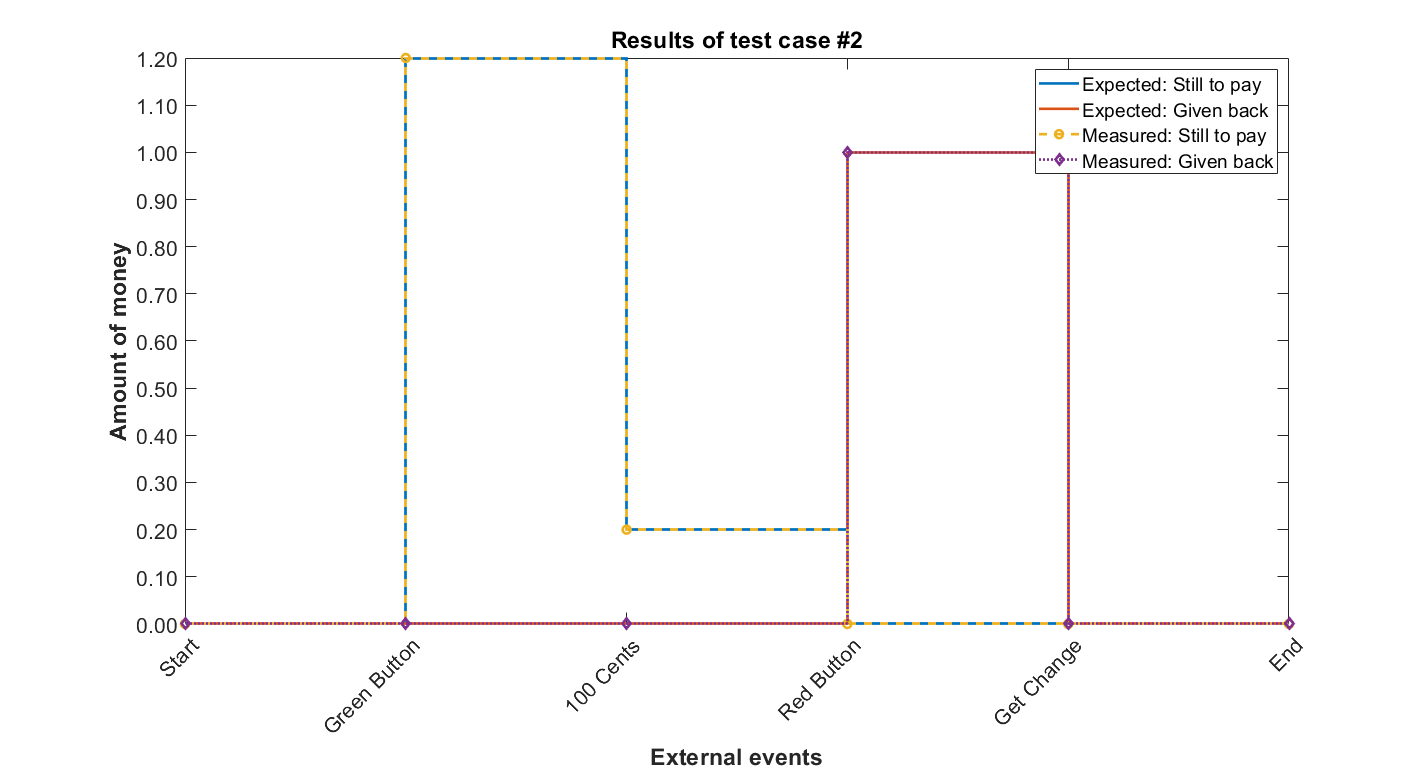


[Terse] Diagnostic logged (2021-02-11 15:53:34):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_d8d915ae-f1a8-43e0-91d5-916c4982eddc.fig
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_d8d915ae-f1a8-43e0-91d5-916c4982eddc.png
.

 Processing the test case #3...


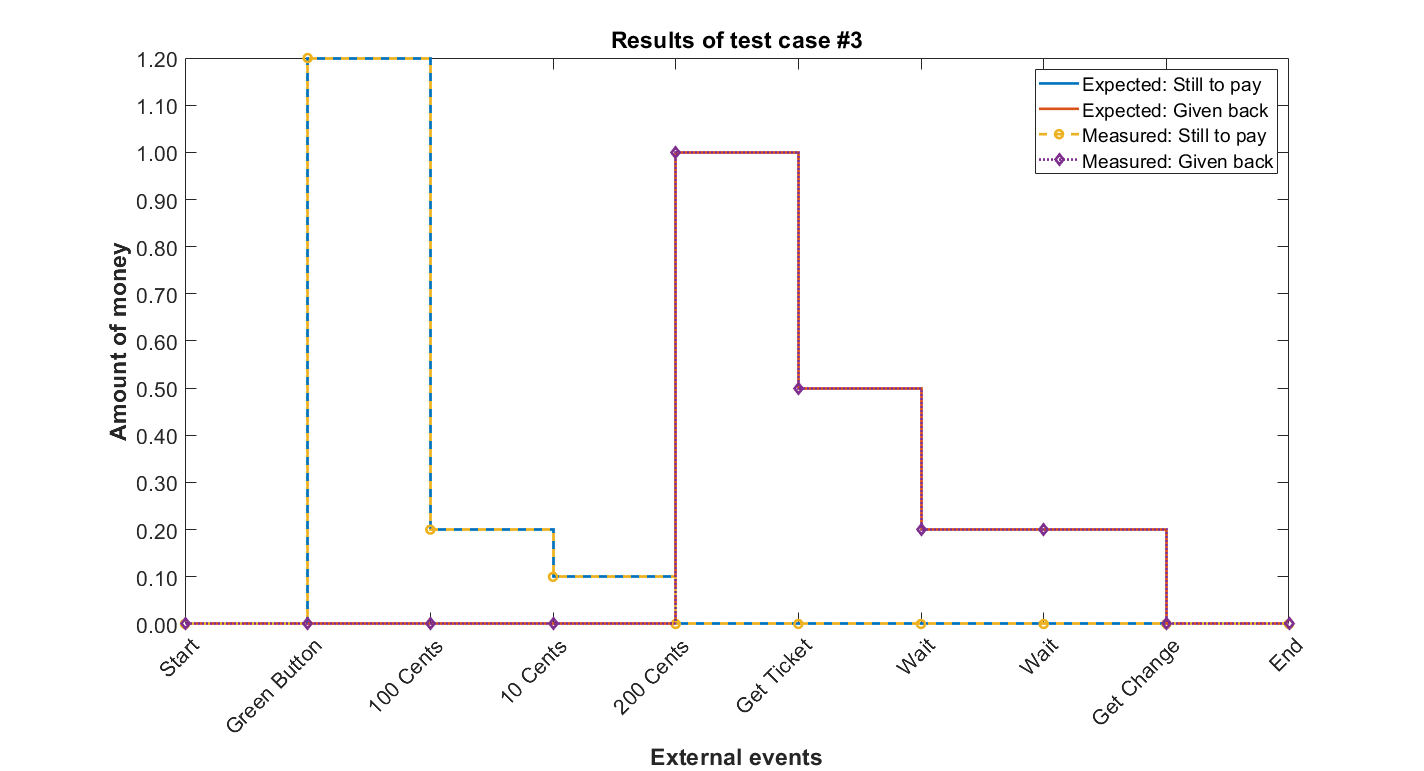


[Terse] Diagnostic logged (2021-02-11 15:54:05):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_2a999880-abd9-4220-98ac-b77cc0d663ab.fig
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_2a999880-abd9-4220-98ac-b77cc0d663ab.png
.

 Processing the test case #4...


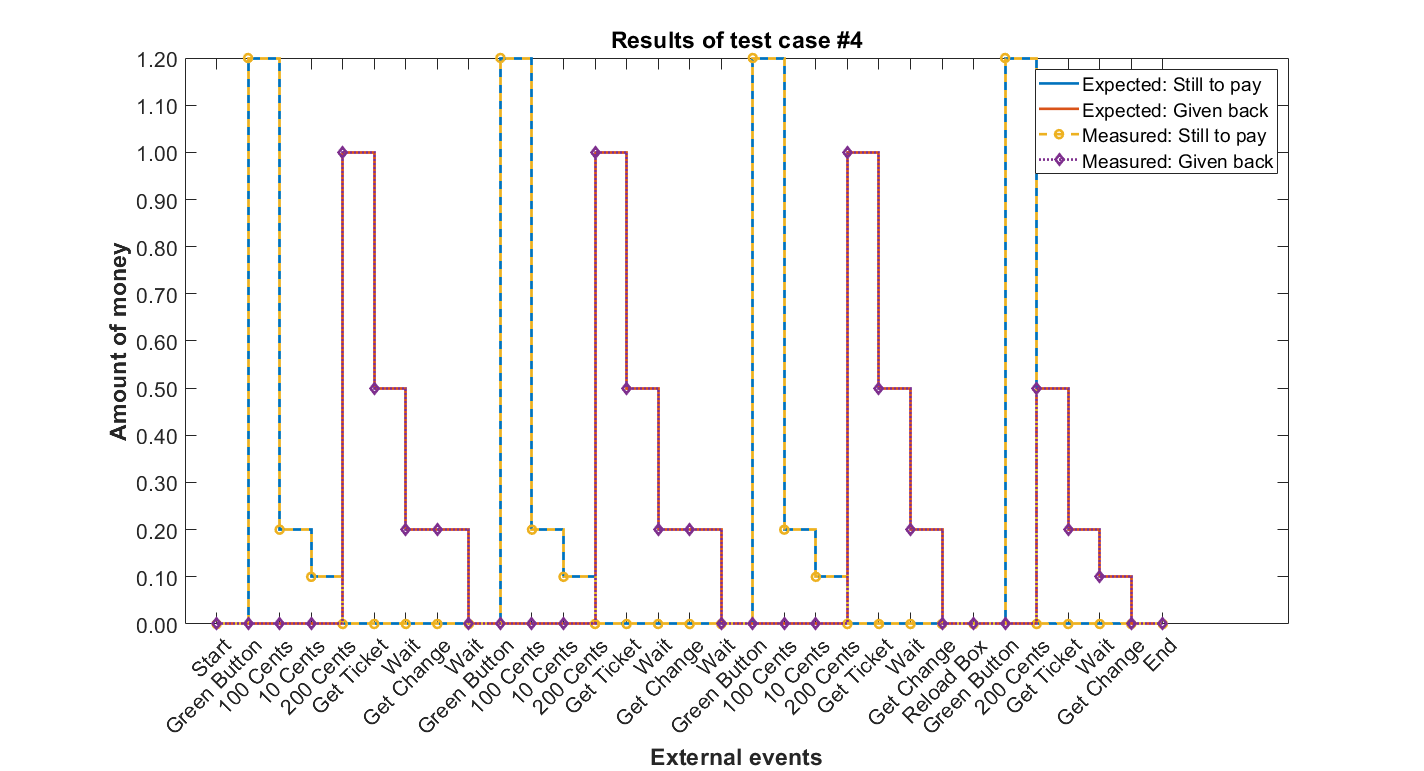


[Terse] Diagnostic logged (2021-02-11 15:55:37):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_f6699916-8ec5-4ea5-8993-d6c859896b9e.fig
--> C:\Users\sebas\AppData\Local\Temp\10008b8e-0c9e-4d6c-a506-eb023f48f803\Figure_f6699916-8ec5-4ea5-8993-d6c859896b9e.png
.
Done TestApp
__________

Generating test report. Please wait.
    Preparing content for the test report.


    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tpcc13ca24_2646_4ec4_ba99_25309236821d\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    true      false       false        28.552     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        24.068     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    true      false       false        30.756     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    true      false       false        91.176     {1×1 struct}

